load("test_functions2.mat","-mat")

f = f3;
gradf = gradf3;
Hessf = Hessf3;

c1 = 1e-4;
rho = 0.8;
btmax = 50;
em = eps();
h = 10*sqrt(em);
disp_int = [-100 100];
x_start = [-50 -15]';
[xk,fk,gradfk_norm,k,xseq,btseq] = newton_general(x_start,f,gradf,Hessf,kmax,tolgrad,c1,rho,btmax,true,"FW","FW",h)

xk =    -3.7793
   -3.2832


fk = 7.8553e-13

gradfk_norm = 5.9005e-14

k = 12

xseq =   -50.0000  -33.4285  -22.4129  -15.1162  -10.3212   -7.2277   -5.3197   -4.2731   -3.8557   -3.7816   -3.7793   -3.7793   -3.7793
  -15.0000  -11.1841   -8.5282   -6.6591   -5.3396   -4.4213   -3.8126   -3.4583   -3.3109   -3.2840   -3.2832   -3.2832   -3.2832


btseq =      0     0     0     0     0     0     0     0     0     0     0     0


## Contour plot

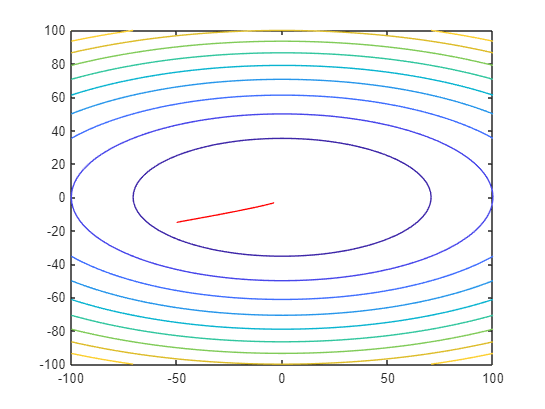

f1_meshgrid = @(X,Y)reshape(f1([X(:),Y(:)]'), size(X));
fcontour(f1_meshgrid,disp_int);
hold on
h = plot(xseq(1,:), xseq(2,:), '-r', 'linewidth', 1, 'markersize', 5);
hold off

## Surface plot

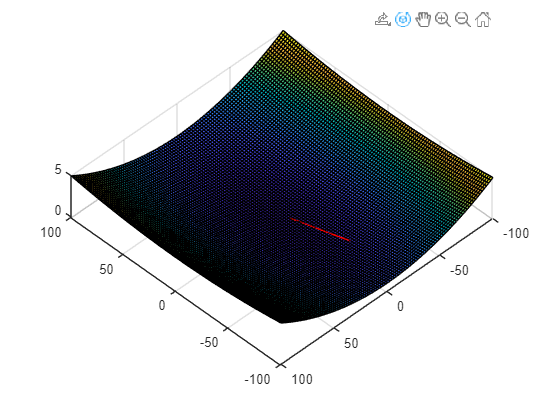

x = linspace(disp_int(1), disp_int(2));
[X,Y] = meshgrid(x,x);
f1_surf = f1_meshgrid(X,Y);

surf(X,Y,f1_surf)
hold on 
view(3)
plot3(xseq(1,:), xseq(2,:), f1_meshgrid(xseq(1,:), xseq(2,:)), "-r")
hold off

## Bar plot

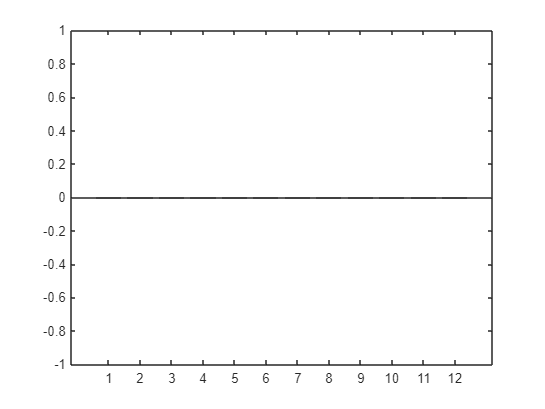

bar(btseq)